Let's start by creating some data on which to perform inference.

rng(14);
n=500;
% rand1 = exprnd(.16,[1,floor(n/3)]);
% rand1 = rand1(rand1<=0.6);
% rand1 = rand1(rand1>0);
% rand3 = exprnd(0.12,[1,floor(n/3)])+0.5;
% rand3 = rand3(rand3<=1);
% rand3 = rand3(rand3>0.5);
lower = 0;
peak = 0.2;
upper = 0.8;
pd = makedist('Triangular','A',lower,'B',peak,'C',upper);
y = random(pd,1,n);

% y = ([rand1])

% y = y(y<=1);
sum(y<0)

ans = 0

sum(y>1)

ans = 0


% knots = [-0.5, 0.0, 0.1, 0.21, 0.31, 0.41, 0.51, 0.6, 0.71, 0.81, 0.91, 1, 1.5];
% d = 11;
knots = [-1e100, 0, 0.11, 0.21, 0.31, 0.41, 0.55, 0.75, 1, 1e100];
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=11;
solve_this = @(a) (constraintFunc(a));
% initial = [-2, log(2), log(2.7), log(1.8), log(1.3), log(0.7), log(0.4), -2];
initial = [-2, log(1), log(2), log(1), log(0.9), log(0.7), log(0.4), -2];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =    -1.9508    0.2884    1.1836    0.3409    0.2121   -0.0171   -0.6606   -1.9244



syms func2(x)
chosen_theta = initial_guess

chosen_theta =    -1.9508    0.2884    1.1836    0.3409    0.2121   -0.0171   -0.6606   -1.9244


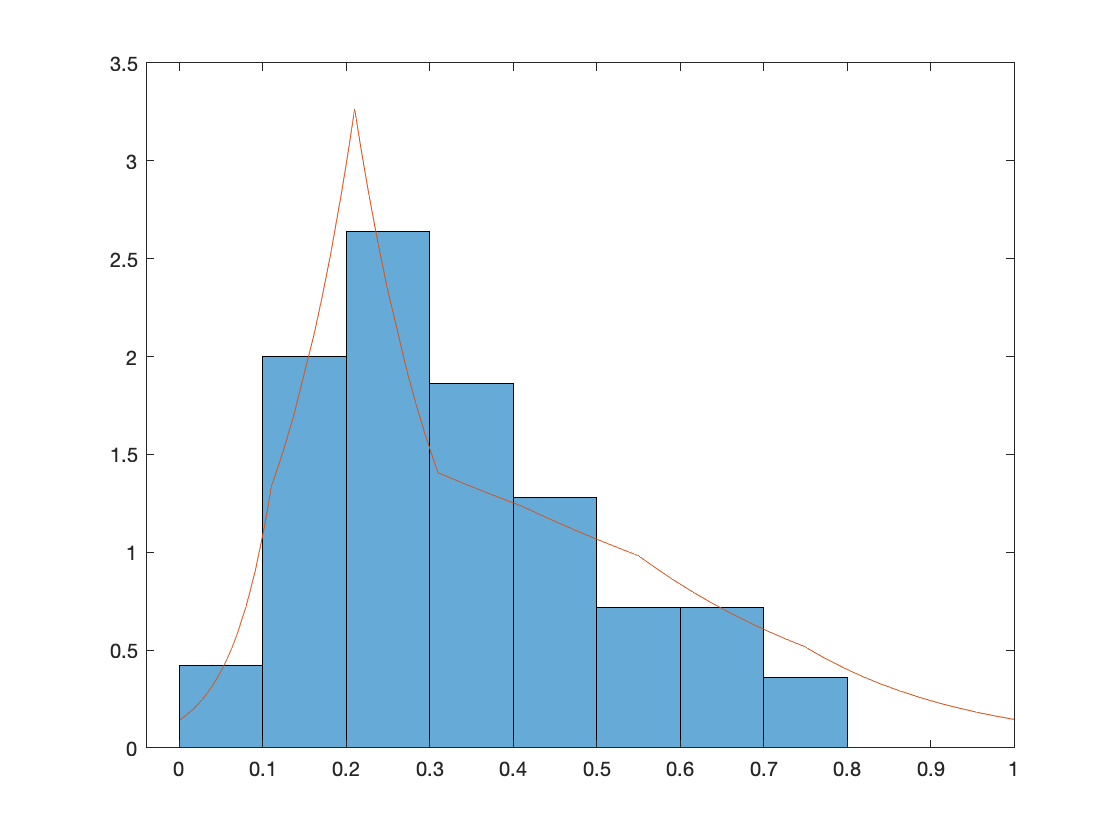

func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))));
histogram(y, 'Normalization','pdf')
hold on
fplot(func2, [0,1])
hold off

We'll select knots based on the graphic, although more principled methods exist.

% Arbitrarily choosing the starting value, with dimension parameter_dim:
data = y;
q0 = initial_guess';
nllFunc = @(x) negLog_fiducial_likelihood(knots,x,data);
conFunc = constraintFunc;

% Set parameters (that I don't quite understand)
nRuns = 1+10;
Nscale = 50000;
runTime = 15; % Time per run in seconds
nTrials = 1000;
doPrint = false;

samplers = struct([]);

h = 5e-6;
M = 4;
L = 500;
hmcOpts = struct('intMethod',0,'doPrint',doPrint,'printMod',10);
samplers(end+1).name = sprintf('CHMC (L = %d)',L);
samplers(end).desc = sprintf('M = %g, h = %g',M,h);
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);
samplers(end).N = ceil(Nscale./L);
samplers(end).style = 'b-';

samplerQs = cell(length(samplers),1+nTrials);
samplerStats = cell(length(samplers),1+nTrials);
samplerNLLs = cell(length(samplers),1+nTrials);
samplerTs = zeros(length(samplers),1+nTrials);
for i = 1:numel(samplers)
    fprintf('%s...',samplers(i).name);
    [q1,qs,samplerStats{i,1}] = samplers(i).func(q0,samplers(i).N);
    samplerQs{i,1} = [q0 qs q1];
    samplerTs(i,1) = samplerStats{i,1}.t/samplerStats{i,1}.N;
%     samplerNLLs{i,1} = nllFunc(samplerQs{i,1});
    
    currN = ceil(runTime./samplerTs(i,1));
    fprintf('%d samples: ',currN);
    fprintf('\n');
end

CHMC (L = 500)...

'constrainedHMC' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/murph/Documents/GitHub/GFI_onManifolds/HMC_logsplines
    /Users/murph/Documents/GitHub/GFI_onManifolds/HMC_onSphere

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in CHMC_logspline (line 69)
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);

mean(samplerStats{1,1}.accepted)
Qs = samplerQs{1,1};
save("HMC_logsplineDraws.mat",'Qs');

Qs = load("HMC_logsplineDraws.mat").Qs

samples = Qs;
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

chosen_theta = samples(:,100)

syms func1(x)
% func(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
%                     (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
%                     (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
%                     (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
%                     (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(7))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
%                     (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(8))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
%                     (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(9))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
%                     (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(10))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
%                     (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(11))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
%                     (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(12))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))) );

func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))));
syms func2(x)
chosen_theta = samples(:,1)
func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))));

% fplot(y, [0,1])

fplot(func1, [0,1])
hold on
fplot(func2, [0,1])
hold off

% double(int(func1, 0, 1))
% double(int(f, 0, 1))